https://www.dsprelated.com/freebooks/filters/Matlab_Analysis_Simplest_Lowpass.html


$$y(n) = x(n) + x(n-1), n = 1,2,...N$$


The implementation is function y = simplpm1(x) at the end of the live script.

N = 10;
x = 1:N;
y = simplpm1(x);

for i=1:N
    disp(sprintf('x(%d)=%f\ty(%d)=%f',i,x(i),i,y(i)));
end

x(1)=1.000000	y(1)=1.000000
x(2)=2.000000	y(2)=3.000000
x(3)=3.000000	y(3)=5.000000
x(4)=4.000000	y(4)=7.000000
x(5)=5.000000	y(5)=9.000000
x(6)=6.000000	y(6)=11.000000
x(7)=7.000000	y(7)=13.000000
x(8)=8.000000	y(8)=15.000000
x(9)=9.000000	y(9)=17.000000
x(10)=10.000000	y(10)=19.000000


Simulated Sine Wave analysis

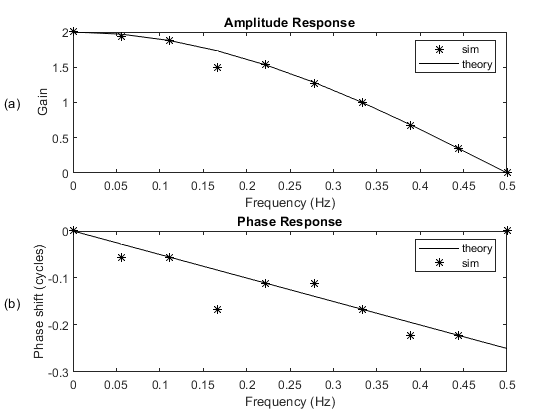

fs = 1;     % arbitrary sample rate

fmax = fs/2;     % nyquist frequency
df = fmax/(N-1);
f = 0:df:fmax;  % frequency axis
dt = 1/fs;
tmax = 10;       % number of seconds to run each sine test
t = 0:dt:tmax;
ampin = 1;
phasein = 0;

% filter coefficients
B = [1,1];
A = 1;
[gains, phases] = swAnal(t,f/fs,B,A);

fig = 1;
% swanalmainplot
figure();
subplot(2,1,1);
ttl = 'Amplitude Response';
freqplot(f,gains,'*k',ttl,'Frequency (Hz)','Gain');
tar = 2*cos(pi*f/fs); % theoretical amplitude response
hold on; freqplot(f,tar,'-k'); hold off;
text(-0.08,mean(ylim),'(a)');
legend('sim','theory')

subplot(2,1,2);
ttl = 'Phase Response';
tpr = -pi*f/fs; % theoretical phase response
pscl = 1/(2*pi);% convert radian phase shift to cycles
freqplot(f,tpr*pscl,'-k',ttl,'Frequency (cycles)',...
    'Phase shift (cycles)');
hold on; freqplot(f,phases*pscl,'*k'); hold off;
text(-0.08,mean(ylim),'(b)');
legend('theory','sim')

%saveplot(plotfile); % set by caller

Analysis with simulated complex sine waves

% fs = 1;     % arbitrary sample rate
% 
% fmax = fs/2;     % nyquist frequency
% df = fmax/(N-1);
% f = 0:df:fmax;  % frequency axis
% dt = 1/fs;
% tmax = 10;       % number of seconds to run each sine test
% t = 0:dt:tmax;
% ampin = 1;
% phasein = 0;
% 
% % filter coefficients
% B = [1,1];
% A = 1;
[gains, phases] = swanalc(t,f/fs,B,A);

ntransient = 1

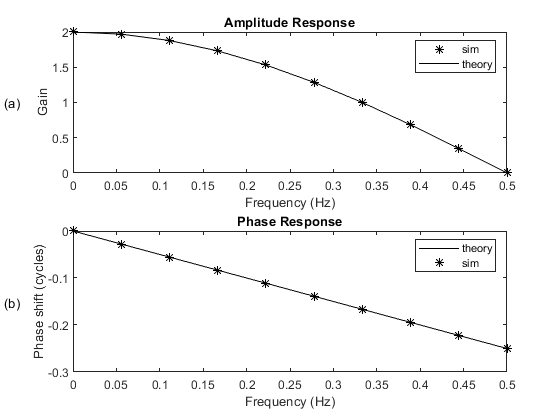


fig = 1;
% swanalmainplot
figure();
subplot(2,1,1);
ttl = 'Amplitude Response';
freqplot(f,gains,'*k',ttl,'Frequency (Hz)','Gain');
tar = 2*cos(pi*f/fs); % theoretical amplitude response
hold on; freqplot(f,tar,'-k'); hold off;
text(-0.08,mean(ylim),'(a)');
legend('sim','theory')

subplot(2,1,2);
ttl = 'Phase Response';
tpr = -pi*f/fs; % theoretical phase response
pscl = 1/(2*pi);% convert radian phase shift to cycles
freqplot(f,tpr*pscl,'-k',ttl,'Frequency (cycles)',...
    'Phase shift (cycles)');
hold on; freqplot(f,phases*pscl,'*k'); hold off;
text(-0.08,mean(ylim),'(b)');
legend('theory','sim')

%saveplot(plotfile); % set by caller

The simplest low pass filter:

function y = simplpm1(x)
B = [1,1];
A = 1;

y = filter(B,A,x);
end

Sine Wave Analysis

function [gains,phases] = swAnal(t,f,B,A)
% SWANAL - Perform sine-wave analysis on filter B(z)/A(z)

ampin = 1;      % input signal amplitude
phasein = 0;    % input signal phase

N = length(f);       % number of test frequencies
gains = zeros(1,N);  % pre-allocate amp-response array
phases = zeros(1,N); % pre-allocate phase-response array
if length(A)==1
    ntransient=length(B)-1; % no. samples to steady state
else
    error('Need to set transient response duration here');
end

for k=1:length(f)    % loop over analysis frequencies
    s = ampin*cos(2*pi*f(k)*t+phasein); % test sinusoid
    y = filter(B,A,s); % run it through the filter
    yss = y(ntransient+1:length(y)); % chop off transient
    % measure output amplitude as max (SHOULD INTERPOLATE):
    [ampout,peakloc] = max(abs(yss)); % ampl. peak & index
    gains(k) = ampout/ampin;  % amplitude response
    if ampout < eps  % eps returns "machine epsilon"
        phaseout=0;    % phase is arbitrary at zero gain
    else
        sphase = 2*pi*f(k)*(peakloc+ntransient-1);
        % compute phase by inverting sinusoid (BAD METHOD):
        phaseout = acos(yss(peakloc)/ampout) - sphase;
        phaseout = wrapToPi(phaseout); % reduce to [-pi,pi)
    end
    phases(k) = phaseout-phasein;
    %swanalplot; % signal plotting script
end
end

Analytic Signal Analysis

function [gains,phases] = swanalc(t,f,B,A)
% SWANALC - Perform COMPLEX sine-wave analysis on the
%           digital filter having transfer function
%           H(z) = B(z)/A(z)

ampin = 1;      % input signal amplitude
phasein = 0;    % input signal phase

N = length(f);       % number of test frequencies
gains = zeros(1,N);  % pre-allocate amp-response array
phases = zeros(1,N); % pre-allocate phase-response array

if length(A)==1, ntransient=length(B)-1, else
    error('Need to set transient response duration here');
end

for k=1:length(f)    % loop over analysis frequencies
    s = ampin*exp(j*2*pi*f(k)*t+phasein); % test sinusoid
    y = filter(B,A,s); % run it through the filter
    yss = y(ntransient+1:length(y)); % chop off transient
    ampout = mean(abs(yss)); % avg instantaneous amplitude
    gains(k) = ampout/ampin; % amplitude response sample
    sss = s(ntransient+1:length(y)); % align with yss
    phases(k) = mean(wrapToPi(angle(yss.*conj(sss))));
end
end

FREQPLOT

function freqplot(fdata, ydata, symbol, ttl, xlab, ylab)
% FREQPLOT - Plot a function of time, Matlab version.

if nargin<6, ylab=''; end
if nargin<5, xlab='Frequency (Hz)'; end
if nargin<4, ttl=''; end
if nargin<3, symbol=''; end
if nargin<2, fdata=0:length(ydata)-1; end

plot(fdata,ydata,symbol); grid;
if ttl, title(ttl); end
if ylab, ylabel(ylab); end
xlabel(xlab);
end